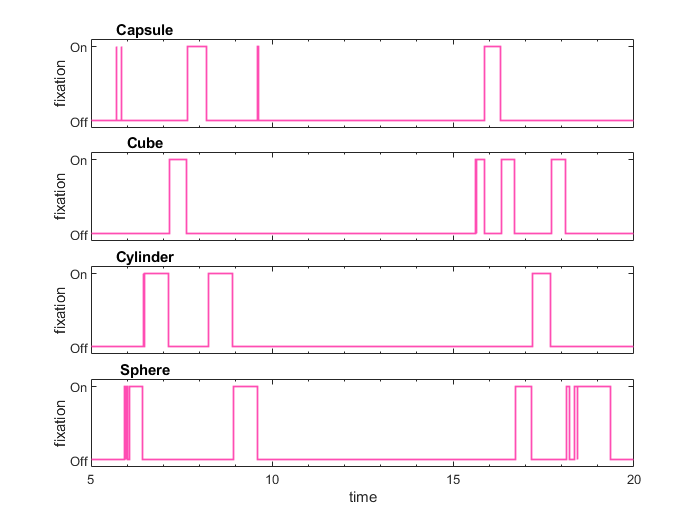

warning('off', 'all')
data_full = readtable('Data_Output.csv');
warning('on', 'all')
objectIDs = unique(data_full.Object);
minx = floor(min(data_full.Time));
maxx = ceil(max(data_full.Time));
tiledlayout(length(objectIDs),1);
for i = 1:length(objectIDs)-1
    temp = data_full(strcmp(data_full.Object,objectIDs(i,1)),:);
    tempTime = [minx; temp.Time;maxx];
    tempFocus = [0;temp.FocusOn_Off;0];
    nexttile
    stairs(tempTime, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])     
    set(gca, "XLabel",[],'XTickLabel',[],'XMinorTick',"on",'XLim',[minx maxx],...
        "ytick",[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
    ylabel('fixation')
    title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])    
end
i = length(objectIDs);
temp = data_full(strcmp(data_full.Object,objectIDs(i,1)),:);
    tempTime = [minx; temp.Time;maxx];
    tempFocus = [0;temp.FocusOn_Off;0];
    nexttile
    stairs(tempTime, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])
    set(gca, 'XMinorTick',"on",'XLim',[minx maxx],...
        'Ytick',[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
    xlabel('time')
    ylabel('fixation')
    title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])   

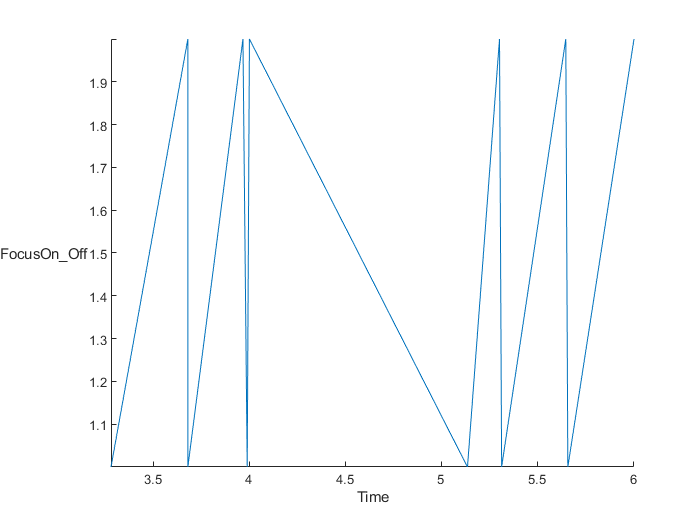

p =   StackedLineChart with properties:

         SourceTable: [12×3 table]
    DisplayVariables: {'FocusOn_Off'}
           XVariable: 'Time'
               Color: [0 0.4470 0.7410]
           LineStyle: '-'
           LineWidth: 0.5000
              Marker: 'none'
          MarkerSize: 6

  Show all properties


% 
% for i:height(objectIDs)
%     strcmp(data_full.Object,objectIDs.Object(1))
% end

% p = stackedplot(data_full, 'XVariable', 'Time'); 


tiledlayout(2,1)
nexttile
stairs(capsule.Time, capsule.FocusOn_Off)
ylim([min(data_full.Time) max(data_full.Time)])
xlim([min(data_full.Time) max(data_full.Time)])
ylim([0.9 2.1])
title('capsule')
nexttile
stairs(cube.Time, cube.FocusOn_Off)
xlim([min(data_full.Time) max(data_full.Time)])
ylim([0.9 2.1])
title('cube')